# Some concepts					

**Pixels and Images:** A pixel is a unit (typically square) of digital information. The pixels are laid out in a grid, which is an image. In Matlab an image is a matrix. You can think of each element of a matrix as a pixel. 					

**Bit: **A Bit is a digit in the binary number system. It can be 0 or 1. 8 bits = 1 byte. 1000 bytes = Megabytes and so on... 

**Pixel depth: **What is an 8 bit image? A 16 bit image? Here, a bit is a unit of color information in a pixel. A 1 bit pixel can be 1 or 0, on or off, which will translate to black or white. An 8 bit pixel has greater pixel depth or bit depth. It can contain and display much more color information. As each bit can have 2 values, 8 bits can have 2x2x2x2x2x2x2x2 = 28 = 256 choices, which means 256 colors. An 8 bit image is likely to be a greyscale image, where one number determines the color of each pixel. An 8-bit color image will typically have 8 bits on each channel (red, green and blue), with a total of 24 bits used to represent color. High resolution color images typically have 16 bits per channel (48 bits total). An image’s file size depends on the total pixel content of the image. Each pixel in your 8 bit image would use 1 byte of memory. The more pixels, and the more pixel depth, the larger the file. 					

**Frame rate: **Frame rate is the frequency at which a device (e.g., your monitor) produces unique consecutive images called frames. Most LCD monitors and laptop screens will be operating at 60 Hz, which means 60 frames per second. 

**Texture, Screen, Window: **You will hear these terms a lot with PTB. Recommended: What’s the difference between window, screen and texture? 

http://psychtoolbox.org/wikka.php?wakka=FaqT extureWindow 

**On screen window: **This is where you display your stimulus. It’s not complicated (unless you attach multiple monitors, you won’t need to worry about this too much). What you want to do is prepare your stimuli and then tell Psychtoolbox to put it on the on screen window. 					

**Off screen window: **Whenever you draw something with PTB it will usually be drawn ‘off screen’. The image exists in memory at this point and is not visible. You then need to use ‘Flip’ function of Screen so that the off screen window gets copied onto the on screen window (the one you can see). 					

**Window pointer (windowPtr): **This is a number that designates a specific window you created. You can create many windows. To use a window, you pass its window pointer to the Screen function. That way, Screen knows which window you want it to work on. 				

**Buffer and ‘Flip’:** A buffer is temporary storage. In the present context, what you will do is prepare what you want to display on the on screen window in a back buffer (off screen) and then copy the contents to the on screen. You can create as many off screen windows as you want. But in PTB3, we refer to the front buffer and a back buffer. We prep an image in the back buffer (see off screen window). When we ‘Flip’, this becomes displayed on the on screen and we get a new buffer to play with (off screen). If you had a movie which had 200 frames, you could display it by flipping the buffers on each frame. This is faster than using 200 off screen windows and copying them to the on screen one by one (although that would also work and older versions of PTB did just that). 

# Open up a screen and get the properties of the screen

% sca;
% close all;
% clear;

% Here we call some default settings for setting up Psychtoolbox
PsychDefaultSetup(2);

% Get the screen numbers. This gives us a number for each of the screens
% attached to our computer.
screens = Screen('Screens');

% To draw we select the maximum of these numbers. So in a situation where we
% have two screens attached to our monitor we will draw to the external
% screen.
screenNumber = max(screens);

% Define black and white (white will be 1 and black 0). This is because
% in general luminace values are defined between 0 and 1 with 255 steps in
% between. With our setup, values defined between 0 and 1.
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);

% Do a simply calculation to calculate the luminance value for grey. This
% will be half the luminace value for white
grey = white / 2;

Open an on screen window using PsychImaging and color it grey

- This function returns a number that identifies the window we have opened "window" and a vector "windowRect". 

- "windowPtr" is a number that designates the window you just created. You can create many windows. To use a window, you pass its windowPtr to the Screen function you want to apply to that window. 

- "windowRect" is a vector of numbers: the first is the X coordinate representing the far left of our screen, the second the Y coordinate representing the top of our screen, the third the X coordinate representing the far right of our screen and finally the Y coordinate representing the bottom of our screen.

[windowPtr, windowRect] = PsychImaging('OpenWindow', screenNumber, grey,[100 100 1000 600]);

PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.18 - Build date: Jan 28 2022).
PTB-INFO: OS support status: macOS version 13 Intel is not yet or no longer tested or officially supported at all for this Psychtoolbox release..
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid priority support, community membership and commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.



PTB-INFO: OpenGL-Renderer is Intel Inc. :: Intel(R) Iris(TM) Plus Graphics 645 :: 2.1 INTEL-20.2.44
PTB-INFO: Renderer has 1536 MB of VRAM and a maximum 3072 MB of texture memory.
PTB-INF

% an alternative way to open a screen:
% [windowPtr,windowRect] = Screen('OpenWindow', 0, grey, [100 100 1000 600]); 
% Screen('OpenWindow',screenNumber,color,pixelSize)

% Testing using a float window:
% [window, windowRect] = PsychImaging('OpenWindow', screenNumber, grey,...
%    [100 100 1000 600], [], [], [], [], [], kPsychGUIWindow); 

% Testing using a transparent full-screened window:
% opacity = 0.8;
% PsychDebugWindowConfiguration([], opacity)
% [windowPtr, windowRect] = PsychImaging('OpenWindow', screenNumber, grey);


% Get the size of the on screen window in pixels, these are the last two
% numbers in "windowRect" and "rect"
[screenXpixels, screenYpixels] = Screen('WindowSize',screenNumber);

% Get the centre coordinate of the window in pixels.
% xCenter = screenXpixels / 2
% yCenter = screenYpixels / 2
[xCenter, yCenter] = RectCenter(windowRect);

% Query the inter-frame-interval. This refers to the minimum possible time
% between drawing to the screen
ifi = Screen('GetFlipInterval', windowPtr);

% We can also determine the refresh rate of our screen. The
% relationship between the two is: ifi = 1 / hertz
hertz = FrameRate(windowPtr);

% color depth of the pixel in bits (radiometric resolution, larger number = higher
% resolution
pixelSize = Screen('PixelSize', windowPtr);


## Get screen coordinates of a moving mouse

% Clear the workspace and the screen
sca;
close all;
clear;

% Here we call some default settings for setting up Psychtoolbox
PsychDefaultSetup(2);

% Get the screen numbers
screens = Screen('Screens');

% Draw to the external screen if avaliable
screenNumber = max(screens);

% Define black and white
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);

% Open an on screen window
opacity = 0.8;
PsychDebugWindowConfiguration([], opacity)
[windowPtr, windowRect] = PsychImaging('OpenWindow', screenNumber, black);



PTB-INFO: This is Psychtoolbox-3 for Apple OS X, under Matlab 64-Bit (Version 3.0.13 - Build date: Jun  1 2016).
PTB-INFO: Support status on this operating system release: OSX 10.11 Supported and tested.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-WARNING: Onscreen window is displayed on a display with display mirroring enabled. This will likely ruin visual timing.
PTB-INFO: Installation of the PsychtoolboxKernelDriver is strongly recommended if you care about precise visual
PTB-INFO: onset timestamping or timing. See 'help PsychtoolboxKernelDriver' for installation instructions.


PTB-INFO: OpenGL-Renderer is ATI Technologies Inc. :: AMD Radeon HD 6970M OpenGL Engine :: 2.1 ATI-1.42.15
PTB-INFO: Renderer has 1024 MB of 


% Get the size of the on screen window
[screenXpixels, screenYpixels] = Screen('WindowSize', windowPtr);

% Query the frame duration
ifi = Screen('GetFlipInterval', windowPtr);

% Setup the text type for the window
Screen('TextFont', windowPtr, 'Ariel');
Screen('TextSize', windowPtr, 50);

% Get the centre coordinate of the window
[xCenter, yCenter] = RectCenter(windowRect);

% Set the mouse to the top left of the screen to start with
SetMouse(0, 0, windowPtr);

% We will update our screen on each frame
waitframes = 1;

% Gets a starting flip for timestamping
vbl = Screen('Flip', windowPtr);

% Run until a key is pressed
while ~KbCheck

    % Get the current position of the mouse
     [x, y, buttons] = GetMouse(windowPtr); 

    % We clamp the values at the maximum values of the screen in X and Y
    % incase people have two monitors connected. This is all we want to
    % show for this basic demo.
    x = min(x, screenXpixels); x = max(0,x);
    y = min(y, screenYpixels); y = max(0,y);

    % Construct our text string
    textString = ['Mouse at X pixel ' num2str(round(x))...
        ' and Y pixel ' num2str(round(y))];

    % Text output of mouse position draw in the centre of the screen
    DrawFormattedText(windowPtr, textString, 'center', 'center', white);

    % Draw a white dot where the mouse cursor is
    Screen('DrawDots', windowPtr, [x y], 10, white, [], 2);

    % Flip to the screen
    vbl = Screen('Flip', windowPtr, vbl + (waitframes - 0.5) * ifi);

end

% Clear the screen
sca;



INFO: PTB's Screen('Flip', 10) command seems to have missed the requested stimulus presentation deadline
INFO: a total of 3 times out of a total of 6616 flips during this session.

INFO: This number is fairly accurate (and indicative of real timing problems in your own code or your system)
INFO: if you provided requested stimulus onset times with the 'when' argument of Screen('Flip', window [, when]);
INFO: If you called Screen('Flip', window); without the 'when' argument, this count is more of a ''mild'' indicator
INFO: of timing behaviour than a hard reliable measurement. Large numbers may indicate problems and should at least
INFO: deserve your closer attention. Cfe. 'help SyncTrouble', the FAQ section at www.psychtoolbox.org and the
INFO: examples in the PDF presentation in PsychDocumentation/Psychtoolbox3-Slides.pdf for more info and timing tips.




# Accurate timing for presenting visual stimuli

## Present visual stimuli which update on each frame

sca;
close all;
clear;

PsychDefaultSetup(2);
screens = Screen('Screens');
screenNumber = max(screens);
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);
grey = white / 2;

% Open an on screen window
[windowPtr, windowRect] = PsychImaging('OpenWindow', screenNumber, grey,[100 100 1000 600]);

PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.18 - Build date: Jan 28 2022).
PTB-INFO: OS support status: macOS version 13 Intel is not yet or no longer tested or officially supported at all for this Psychtoolbox release..
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid priority support, community membership and commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.



PTB-INFO: OpenGL-Renderer is Intel Inc. :: Intel(R) Iris(TM) Plus Graphics 645 :: 2.1 INTEL-20.2.44
PTB-INFO: Renderer has 1536 MB of VRAM and a maximum 3072 MB of texture memory.
PTB-INF


% Measure the vertical refresh rate of the monitor
ifi = Screen('GetFlipInterval', windowPtr);

% Retreive the maximum priority number
topPriorityLevel = MaxPriority(windowPtr);

% Length of time and number of frames we will use for each drawing test
numSecs = 1;
numFrames = round(numSecs / ifi);

% Number of frames to wait when specifying good timing. Note: the use of
% wait frames is to show a generalisable coding. For example, by using
% waitframes = 2 one would flip on every other frame. See the PTB
% documentation for details. In what follows we flip every frame.
waitframes = 1;

## Screen flip logic

The vbl on the left hand side is a variable in which the time that the screen 'flipped' is stored.

The right hand side is a command from PTB telling the window to flip - Screen('Flip',window) - the vbl + (waitframes - 0.5)*ifi is an additional parameter in the flip instructions telling the computer to wait for that moment to flip the screen. i.e. Screen('Flip', window, **when**)

On each loop / frame, you flip the screen and get the time of the flip in the vbl variable. In the next loop, you time the next flip according to the last one, i.e. vbl + [some number of seconds]. Thus your line of code is both using the previous value of vbl in the function call, and setting it to a new value which the function returns. vbl is updated on a rolling basis. vbl is the 'vertical blanking' time, a pretty accurate estimate of when your monitor actually refreshed*, so aligning frames to this is a good idea.

The question is how far ahead from the last vbl to do the next flip. ifi is the time between refreshes, or 1/[your monitor refresh rate in Hz]. Lets ignore waitframes for now and assume you want to flip on every monitor refresh, i.e. waitframes = 1.

Then your line of code simplifies to:

% vbl  = Screen('Flip', windowPtr, vbl + ifi/2);

So we are asking to flip half an ifi before the next refresh. **Why not just ask to flip on the next refresh, i.e.** **vbl + ifi****?** Because that sum is a floating-point calculation and may contain small rounding errors. Screen('Flip') can only swap the screen buffers on the next monitor refresh, so what happens if the error in that sum slightly overshoots? Then you've just asked for a flip time slightly beyond the monitor refresh you actually wanted, and PTB has to wait almost an entire ifi to actually flip**.

So we ask for a flip time some amount (less than ifi) *before* the desired monitor refresh - ifi/2is reasonable. We're really saying "do the next flip ASAP after vbl+ifi/2", knowing both that Screen('Flip') can't actually do it prior to the refresh, and safe in the knowledge that we have ifi/2 leeway to absorb minor inaccuracies in the timing calculation.

**Example code**

Priority(topPriorityLevel);
% first set the PTB prority level to maximum. This means PTB will take
% processing priority over other system and applicaiton processes.

vbl = Screen('Flip', windowPtr);
for frame = 1:numFrames

    % Color the screen purple
    Screen('FillRect', windowPtr, [0.5 0 0.5], [100 100 1000 600]);
    
    % Tell PTB no more drawing commands will be issued until the next flip
    Screen('DrawingFinished', windowPtr);
    
        % This can help acheive good timing when one
        % is needing to do additional non-PTB processing between setting up drawing
        % and flipping to the screen. Thus, you would only use this technique if
        % you were doing this.

    % Flip to the screen
    vbl = Screen('Flip', windowPtr, vbl + (waitframes - 0.5) * ifi);

end
Priority(0);

## Update an image on the screen at a rate different to that of the monitors refresh rate (eg. update every second)

This way of coding is more optimal for drawing static stimuli which do not change on every screen refresh

sca;
close all;
clear;

PsychDefaultSetup(2);

screens = Screen('Screens');
screenNumber = max(screens);
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);
grey = white / 2;

[windowPtr, windowRect] = PsychImaging('OpenWindow', screenNumber, grey,[100 100 1000 600]);
ifi = Screen('GetFlipInterval', windowPtr);

% Here we use to a waitframes number greater then 1 to flip at a rate not
% equal to the monitors refreash rate. For this example, once per second,
% to the nearest frame
flipSecs = 1;
waitframes = round(flipSecs / ifi);

% Flip outside of the loop to get a time stamp
vbl = Screen('Flip', windowPtr);

kb.escKey = KbName('ESCAPE');
kb.keyIsDown = 0; 
kb.keyCode = zeros(1,256);

% Run until a key is pressed
while ~kb.keyCode(kb.escKey)
    
    % Color the screen a random color
    Screen('FillRect', windowPtr, rand(1, 3));

    % Flip to the screen
    vbl = Screen('Flip', windowPtr, vbl + (waitframes - 0.5) * ifi);

end

% Clear the screen.
sca;


# Draw on the screen

## Draw a single dot

% Clear the workspace and the screen
sca;
close all;
clear;
PsychDefaultSetup(2);

% Seed the random number generator. Here we use the an older way to be
% compatible with older systems.
rng('shuffle')

% Set up screen
screens = Screen('Screens');
screenNumber = max(screens);
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);

[window, windowRect] = PsychImaging('OpenWindow', screenNumber, black,[100 100 1000 600]);

PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.18 - Build date: Jan 28 2022).
PTB-INFO: OS support status: macOS version 13 Intel is not yet or no longer tested or officially supported at all for this Psychtoolbox release..
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid priority support, community membership and commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.



PTB-INFO: OpenGL-Renderer is Intel Inc. :: Intel(R) Iris(TM) Plus Graphics 645 :: 2.1 INTEL-20.2.44
PTB-INFO: Renderer has 1536 MB of VRAM and a maximum 3072 MB of texture memory.
PTB-INF

Error using Screen
See error message printed above.

Error in PsychImaging (line 2339)
            [win, winRect] = Screen('OpenWindow', screenid, clearcolor, winRect, pixelSize, numbuffers, stereomode, multiSample, imagingMode, specialFlags, clientRect, fbOverrideRect, vrrParams);


[screenXpixels, screenYpixels] = Screen('WindowSize', window);
[xCenter, yCenter] = RectCenter(windowRect);

% Enable alpha blending for anti-aliasing
% For help see: Screen BlendFunction?
% Also see: Chapter 6 of the OpenGL programming guide
Screen('BlendFunction', window, GL_SRC_ALPHA, GL_ONE_MINUS_SRC_ALPHA);

% Set the color of our dot to full red. Color is defined by red green
% and blue components (RGB). So we have three numbers which
% define our RGB values. The maximum number for each is 1 and the minimum
% 0. So, "full red" is [1 0 0]. "Full green" [0 1 0] and "full blue" [0 0
% 1]. Play around with these numbers and see the result.
dotColor = [1 0 0];

% Determine a random X and Y position for our dot. NOTE: As dot position is
% randomised each time you run the script the output picture will show the
% dot in a different position. Similarly, when you run the script the
% position of the dot will be randomised each time. NOTE also, that if the
% dot is drawn at the edge of the screen some of it might not be visible.
dotXpos = rand * screenXpixels;
dotYpos = rand * screenYpixels;

% Dot size in pixels
dotSizePix = 20;

% Draw the dot to the screen. For information on the command used in
% this line type "Screen DrawDots?" at the command line (without the
% brackets) and press enter. Here we used good antialiasing to get nice
% smooth edges
Screen('DrawDots', window, [dotXpos dotYpos], dotSizePix, dotColor, [], 2);

% Flip to the screen. This command basically draws all of our previous
% commands onto the screen. See later demos in the animation section on more
% timing details. And how to demos in this section on how to draw multiple
% rects at once.
% For help see: Screen Flip?
Screen('Flip', window);

## Draw a dot grid

% Clear the workspace and the screen
sca;
close all;
clear;

% Here we call some default settings for setting up Psychtoolbox
PsychDefaultSetup(2);

% Seed the random number generator. Here we use the an older way to be
% compatible with older systems.
rng('shuffle')

% screen set up
screens = Screen('Screens');
screenNumber = max(screens);
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);
opacity = 0.8;
PsychDebugWindowConfiguration([], opacity)
[window, windowRect] = PsychImaging('OpenWindow', screenNumber, black);

PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.18 - Build date: Jan 28 2022).
PTB-INFO: OS support status: macOS version 13 Intel is not yet or no longer tested or officially supported at all for this Psychtoolbox release..
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid priority support, community membership and commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.



PTB-INFO: OpenGL-Renderer is Intel Inc. :: Intel(R) Iris(TM) Plus Graphics 645 :: 2.1 INTEL-20.2.44
PTB-INFO: Renderer has 1536 MB of VRAM and a maximum 3072 MB of texture memory.
PTB-INF

% [window, windowRect] = PsychImaging('OpenWindow', screenNumber, black,[100 100 1000 600]);
[screenXpixels, screenYpixels] = Screen('WindowSize', window);
[xCenter, yCenter] = RectCenter(windowRect);
Screen('BlendFunction', window, GL_SRC_ALPHA, GL_ONE_MINUS_SRC_ALPHA);

% Use the meshgrid command to create our base dot coordinates. This will
% simply be a grid of equally spaced coordinates in the X and Y dimensions,
% centered on 0,0
% For help see: help meshgrid
dim = 10;
[x, y] = meshgrid(-dim:1:dim, -dim:1:dim);

% Here we scale the grid so that it is in pixel coordinates. We just scale
% it by the screen size so that it will fit. This is simply a
% multiplication. Notice the "." before the multiplicaiton sign. This
% allows us to multiply each number in the matrix by the scaling value.
pixelScaleY = screenYpixels / (dim * 2 + 2);
pixelScaleX = screenXpixels / (dim * 2 + 2);
x = x .* pixelScaleX;
y = y .* pixelScaleY;

% Calculate the number of dots
% For help see: help numel
numDots = numel(x);

% Make the matrix of positions for the dots. This need to be a two row
% vector. The top row will be the X coordinate of the dot and the bottom
% row the Y coordinate of the dot. Each column represents a single dot. For
% help see: help reshape
dotPositionMatrix = [reshape(x, 1, numDots); reshape(y, 1, numDots)];

% We can define a center for the dot coordinates to be relaitive to. Here
% we set the centre to be the centre of the screen
dotCenter = [xCenter yCenter];

% Set the color of our dot to be random i.e. a random number between 0 and
% 1
dotColors = rand(3, numDots) .* white;

% Set the size of the dots randomly between 10 and 30 pixels
dotSizes = rand(1, numDots) .* 20 + 10;

% Draw all of our dots to the screen in a single line of code
% For help see: Screen DrawDots
Screen('DrawDots', window, dotPositionMatrix,...
    dotSizes, dotColors, dotCenter, 2);

% Flip to the screen. This command basically draws all of our previous
% commands onto the screen. See later demos in the animation section on more
% timing details. And how to demos in this section on how to draw multiple
% rects at once.
% For help see: Screen Flip?
Screen('Flip', window);

% Now we have drawn to the screen we wait for a keyboard button press (any
% key) to terminate the demo. For help see: help KbStrokeWait
KbStrokeWait;
% 
% 
sca;

## Draw fixation cross

sca;
close all;
clear;

PsychDefaultSetup(2);
screens = Screen('Screens');
screenNumber = max(screens);
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);
opacity = 0.8;
PsychDebugWindowConfiguration([], opacity)

[window, windowRect] = PsychImaging('OpenWindow', screenNumber, black);



PTB-INFO: This is Psychtoolbox-3 for Apple OS X, under Matlab 64-Bit (Version 3.0.13 - Build date: Jun  1 2016).
PTB-INFO: Support status on this operating system release: OSX 10.11 Supported and tested.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-WARNING: Onscreen window is displayed on a display with display mirroring enabled. This will likely ruin visual timing.
PTB-INFO: Installation of the PsychtoolboxKernelDriver is strongly recommended if you care about precise visual
PTB-INFO: onset timestamping or timing. See 'help PsychtoolboxKernelDriver' for installation instructions.


PTB-INFO: OpenGL-Renderer is ATI Technologies Inc. :: AMD Radeon HD 6970M OpenGL Engine :: 2.1 ATI-1.42.15
PTB-INFO: Renderer has 1024 MB of 

[screenXpixels, screenYpixels] = Screen('WindowSize', window);

ifi = Screen('GetFlipInterval', window);
Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

% Setup the text type for the window
Screen('TextFont', window, 'Ariel');
Screen('TextSize', window, 36);

% Get the centre coordinate of the window
[xCenter, yCenter] = RectCenter(windowRect);

% Here we set the size of the arms of our fixation cross
fixCrossDimPix = 40;

% Now we set the coordinates (these are all relative to zero we will let
% the drawing routine center the cross in the center of our monitor for us)
xCoords = [-fixCrossDimPix fixCrossDimPix 0 0];
yCoords = [0 0 -fixCrossDimPix fixCrossDimPix];
allCoords = [xCoords; yCoords];

% Set the line width for our fixation cross
lineWidthPix = 4;

% Draw the fixation cross in white, set it to the center of our screen and
% set good quality antialiasing
Screen('DrawLines', window, allCoords,...
    lineWidthPix, white, [xCenter yCenter], 2);

% Flip to the screen
Screen('Flip', window);


## Draw a gaussian blob

sca;
close all;
clear;

PsychDefaultSetup(2);
screens = Screen('Screens');
screenNumber = max(screens);
black = BlackIndex(screenNumber);
opacity = 0.3;
PsychDebugWindowConfiguration([], opacity)

[windowPtr, windowRect] = PsychImaging('OpenWindow', screenNumber, black);

Tried to prepare a new configuration phase via PsychImaging('PrepareConfiguration'), but did not finalize the previous phase yet.
You must call the PsychImaging('OpenWindow', ...); command at least once to open an onscreen
window according to the provided settings, before you can specify settings for additional onscreen windows.

The most likely reason you see this error message is because your script aborted with some error
before it managed to open the onscreen window. In that case it is best practice to execute a 'clear all'
command at the Matlab/Octave prompt before you restart your script.

I will restart configuration now and forget the previously made PsychImaging('AddTask', ...); settings.




PTB-INFO: This is Psychtoolbox-3 for Apple OS X, under Matlab 64-Bit (Version 3.0.13 - Build date: Jun  1 2016).
PTB-INFO: Support status on this operating system release: OSX 10.11 Supported and tested.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: Installation of the PsychtoolboxKernelDriver is strongly recommended if you care about precise visual
PTB-INFO: onset timestamping or timing. See 'help PsychtoolboxKernelDriver' for installation instructions.


PTB-INFO: OpenGL-Renderer is ATI Technologies Inc. :: AMD Radeon HD 6970M OpenGL Engine :: 2.1 ATI-1.42.15
PTB-INFO: Renderer has 1024 MB of VRAM and a maximum 1009 MB of texture memory.
PTB-INFO: VBL startline = 1080 , VBL Endline = -1
PTB-INFO: Beamposition queri

[ScreenInfo.xaxis, ScreenInfo.yaxis] = Screen('WindowSize',windowPtr);
[center(1), center(2)]     = RectCenter(windowRect);
ScreenInfo.xmid            = center(1); % horizontal center
ScreenInfo.ymid            = center(2); % vertical center
ScreenInfo.backgroundColor = 105;
ScreenInfo.numPixels_perCM = 7.5;
ScreenInfo.liftingYaxis    = 300; 

ifi = Screen('GetFlipInterval', windowPtr);
% Screen('BlendFunction', windowPtr, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

% intensity of standard stimulus
    VSinfo.standard                      = 0.2; % a ratio between 0 to 1 to be multipled by 255
    pblack = 1/8; % set contrast to 255*1/8 for the "black" background
    
% define the visual stimuli

    VSinfo.numFrames                     = 6;
    VSinfo.duration                      = VSinfo.numFrames * ifi;%s
    VSinfo.width                         = 401; %(pixel) Increasing this value will make the cloud more blurry
    VSinfo.boxSize                       = 201; %This is the box size for each cloud.
    %set the parameters for the visual stimuli
    VSinfo.blackScreen                   = 255 * pblack *ones(ScreenInfo.xaxis,ScreenInfo.yaxis);
    VSinfo.blankScreen                   = zeros(ScreenInfo.xaxis,ScreenInfo.yaxis);
    x                                    = 1:1:VSinfo.boxSize; y = x;
    VSinfo.x                             = x; VSinfo.y = y;
    [X,Y]                                = meshgrid(x,y);
    VSinfo.cloud                         = mvnpdf([X(:) Y(:)],[median(x) median(y)],...
    [VSinfo.width 0; 0 VSinfo.width]);
    pscale                               = (1-pblack)/max(VSinfo.cloud); % the max contrast of the blob adds the background contrast should <= 1
    VSinfo.cloud                         = VSinfo.cloud .* pscale;
    VSinfo.Cloud                         = 255.*VSinfo.standard.*reshape(VSinfo.cloud,length(x),length(y));
    VSinfo.blk_texture                   = Screen('MakeTexture', windowPtr, VSinfo.blackScreen,[],[],[],2);

% Display visual stimuli
targetLoc = ScreenInfo.xmid;
blob_coordinates = [targetLoc, ScreenInfo.liftingYaxis];    
dotCloud = generateOneBlob(windowPtr,blob_coordinates,VSinfo,ScreenInfo);
 
for j = 1:VSinfo.numFrames %100ms  
        Screen('DrawTexture',windowPtr, VSinfo.Cloud,[],[0,0,ScreenInfo.xaxis, ScreenInfo.yaxis]);
        Screen('Flip',windowPtr);
end 

Error in function DrawTexture: 	Wrong size argument supplied
	Discrepancy between a specified and supplied argument:
		Specified Argument Description:
			direction: Input
			position: 2
			presence:
			formats allowed:
				double
			minimum M: 1
			maximum M: 1
			minimum N: 1
			maximum N: 1
			minimum P: 1
			maximum P: 1
		Provided Argument Description:
			direction: Input
			position: 2
			presence: present
			format:double
			 number of dimensions: 2
				 M: 201
				 N: 201
				 P: 1




Error using Screen
Usage:

Screen('DrawTexture', windowPointer, texturePointer [,sourceRect] [,destinationRect] [,rotationAngle] [, filterMode] [, globalAlpha] [, modulateColor] [, textureShader] [, specialFlags] [, auxParameters]);


% for k = 1:30 %500ms blank screen
%         Screen('DrawTexture',windowPtr, VSinfo.blk_texture,[],...
%             [0,0,ScreenInfo.xaxis, ScreenInfo.yaxis]);
%         Screen('Flip',windowPtr);
% end

# Text

## Draw basic text

close all;
clear;
sca


PsychDefaultSetup(2);
screens = Screen('Screens');
screenNumber = max(screens);

black = BlackIndex(screenNumber);
white = WhiteIndex(screenNumber);
grey = white / 2;

opacity = 0.8;
PsychDebugWindowConfiguration([], opacity)
[window, windowRect] = PsychImaging('OpenWindow', screenNumber, black);

PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.18 - Build date: Jan 28 2022).
PTB-INFO: OS support status: macOS version 13 Intel is not yet or no longer tested or officially supported at all for this Psychtoolbox release..
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid priority support, community membership and commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.



PTB-INFO: OpenGL-Renderer is Intel Inc. :: Intel(R) Iris(TM) Plus Graphics 645 :: 2.1 INTEL-20.2.44
PTB-INFO: Renderer has 1536 MB of VRAM and a maximum 3072 MB of texture memory.
PTB-INF


% Set the blend funciton for the screen
Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

[screenXpixels, screenYpixels] = Screen('WindowSize', window);
[xCenter, yCenter] = RectCenter(windowRect);

% Draw text in the upper portion of the screen with the default font in red
Screen('TextSize', window, 50);
DrawFormattedText(window, 'Hello World', 'center',...
    screenYpixels * 0.25, [1 0 0]);

% Draw text in the middle of the screen in Courier in white
Screen('TextSize', window, 50);
Screen('TextFont', window, 'Courier');
DrawFormattedText(window, 'Hello World', 'center', 'center', white);

% Draw text in the bottom of the screen in Times in blue
Screen('TextSize', window, 50);
Screen('TextFont', window, 'Courier');
DrawFormattedText(window, 'Hello World', 'center',...
    screenYpixels * 0.75, [0 0 1]);

% Flip to the screen
Screen('Flip', window);


## Draw multiple lines of text 

% Clear the workspace and the screen
close all;
clear;
sca

% Here we call some default settings for setting up Psychtoolbox
PsychDefaultSetup(2);

% Get the screen numbers
screens = Screen('Screens');

% Select the external screen if it is present, else revert to the native
% screen
screenNumber = max(screens);

% Define black, white and grey
black = BlackIndex(screenNumber);
white = WhiteIndex(screenNumber);
grey = white / 2;

opacity = 0.8;
PsychDebugWindowConfiguration([], opacity)
[window, windowRect] = PsychImaging('OpenWindow', screenNumber, black);

PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.18 - Build date: Jan 28 2022).
PTB-INFO: OS support status: macOS version 13 Intel is not yet or no longer tested or officially supported at all for this Psychtoolbox release..
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid priority support, community membership and commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.



PTB-INFO: OpenGL-Renderer is Intel Inc. :: Intel(R) Iris(TM) Plus Graphics 645 :: 2.1 INTEL-20.2.44
PTB-INFO: Renderer has 1536 MB of VRAM and a maximum 3072 MB of texture memory.
PTB-INF


% Set the blend funciton for the screen
Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

% Get the size of the on screen window in pixels
% For help see: Screen WindowSize?
[screenXpixels, screenYpixels] = Screen('WindowSize', window);

% Get the centre coordinate of the window in pixels
% For help see: help RectCenter
[xCenter, yCenter] = RectCenter(windowRect);

% Lets write three lines of text, the first and second right after one
% another, and the third with a line space in between. To add line spaces
% we use the special characters "\n"
line1 = 'Hello World';
line2 = '\n This is the second line';
line3 = '\n This is the third line';

% Draw all the text in one go
Screen('TextSize', window, 70);
DrawFormattedText(window, [line1 line2 line3],...
    'center', screenYpixels * 0.25, white);

% Flip to the screen
Screen('Flip', window);


# Animated texture

## Draw a drifting gabor 

% Clear the workspace and the screen
sca;
close all;
clear;

% Setup PTB with some default values
PsychDefaultSetup(2);

% Set the screen number to the external secondary monitor if there is one
% connected
screenNumber = max(Screen('Screens'));

% Define black, white and grey
white = WhiteIndex(screenNumber);
black = BlackIndex(screenNumber);
grey = white / 2;

% Open the screen
[window, windowRect] = PsychImaging('OpenWindow', screenNumber, grey,...
    [], 32, 2, [], [], kPsychNeedRetinaResolution);



PTB-INFO: This is Psychtoolbox-3 for Apple OS X, under Matlab 64-Bit (Version 3.0.13 - Build date: Jun  1 2016).
PTB-INFO: Support status on this operating system release: OSX 10.11 Supported and tested.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: Installation of the PsychtoolboxKernelDriver is strongly recommended if you care about precise visual
PTB-INFO: onset timestamping or timing. See 'help PsychtoolboxKernelDriver' for installation instructions.


PTB-INFO: OpenGL-Renderer is ATI Technologies Inc. :: AMD Radeon HD 6970M OpenGL Engine :: 2.1 ATI-1.42.15
PTB-INFO: Renderer has 1024 MB of VRAM and a maximum 1009 MB of texture memory.
PTB-INFO: VBL startline = 1080 , VBL Endline = -1
PTB-INFO: Beamposition queri


% Get the vertical refresh rate of the monitor
ifi = Screen('GetFlipInterval', window);

% Set maximum priority level
topPriorityLevel = MaxPriority(window);
Priority(topPriorityLevel);


%--------------------
% Gabor information
%--------------------

% Dimension of the region where will draw the Gabor in pixels
gaborDimPix = windowRect(4) / 2;

% Sigma of Gaussian
sigma = gaborDimPix / 7;

% Obvious Parameters
orientation = 0;
contrast = 1;
aspectRatio = 1.0;
phase = 0;

% Spatial Frequency (Cycles Per Pixel)
% One Cycle = Grey-Black-Grey-White- Grey i.e. One Black and One White Lobe
numCycles = 10;
freq = numCycles / gaborDimPix;

% Build a procedural gabor texture (Note: to get a "standard" Gabor patch
% we set a grey background  offset, disable normalisation, and set a
% pre-contrast multiplier of 0.5).
backgroundOffset = [0.5 0.5 0.5 0];
disableNorm = 1;
preContrastMultiplier = 1;
gabortex = CreateProceduralGabor(window, gaborDimPix, gaborDimPix, [],...
    backgroundOffset, disableNorm, preContrastMultiplier);

Compiling all shaders matching BasicGaborShader * into a GLSL program.
Building a fragment shader:Reading shader from file /e/3.3/p3/hong/Desktop/Project5/Psychtoolbox/PsychOpenGL/PsychGLSLShaders/BasicGaborShader.frag.txt ...
Building a vertex shader:Reading shader from file /e/3.3/p3/hong/Desktop/Project5/Psychtoolbox/PsychOpenGL/PsychGLSLShaders/BasicGaborShader.vert.txt ...



% Randomise the phase of the Gabors and make a properties matrix.
propertiesMat = [phase, freq, sigma, contrast, aspectRatio, 0, 0, 0];


%------------------------------------------
%    Draw stuff - button press to exit
%------------------------------------------

% FLip to the vertical retrace rate
vbl = Screen('Flip', window);

% We will update the stimulus on each frame
waitframes = 1;

% We choose an arbitary value at which our Gabor will drift
phasePerFrame = 10 * pi; 

while ~KbCheck

    % Draw the Gabor. By default PTB will draw this in the center of the screen
    % for us.
    Screen('DrawTextures', window, gabortex, [], [], orientation, [], [], [], [],...
        kPsychDontDoRotation, propertiesMat');

    % Flip to the screen
    vbl = Screen('Flip', window, vbl + (waitframes - 0.5) * ifi);

    % Update the phase element of the properties matrix (we could if we
    % want to update any or all of the properties on each frame. Here the
    % Gabor will drift to the left.
    propertiesMat(1) = propertiesMat(1) + phasePerFrame;

end

% Clear screen
sca;

# Run full experiment

% Clear the workspace
close all;
clear;
sca; 

 % Setup PTB with some default values 
PsychDefaultSetup(2);

% Seed the random number generator
rng('shuffle')

% Set the screen number to the external secondary monitor if there is one
% connected 
screenNumber = max(Screen('Screens'));

% Define black, white and grey
white = WhiteIndex(screenNumber);
grey = white / 2;
black = BlackIndex(screenNumber);

% Open the screen
[window, windowRect] = PsychImaging('OpenWindow', screenNumber, grey, [], 32, 2);



PTB-INFO: This is Psychtoolbox-3 for Apple OS X, under Matlab 64-Bit (Version 3.0.13 - Build date: Jun  1 2016).
PTB-INFO: Support status on this operating system release: OSX 10.11 Supported and tested.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: Installation of the PsychtoolboxKernelDriver is strongly recommended if you care about precise visual
PTB-INFO: onset timestamping or timing. See 'help PsychtoolboxKernelDriver' for installation instructions.


PTB-INFO: OpenGL-Renderer is ATI Technologies Inc. :: AMD Radeon HD 6970M OpenGL Engine :: 2.1 ATI-1.42.15
PTB-INFO: Renderer has 1024 MB of VRAM and a maximum 1009 MB of texture memory.
PTB-INFO: VBL startline = 1080 , VBL Endline = -1
PTB-INFO: Beamposition queri


% Flip to clear
Screen('Flip', window);

% Query the frame duration
ifi = Screen('GetFlipInterval', window);

% Set the text size
Screen('TextSize', window, 60);

% Get the centre coordinate of the window
[xCenter, yCenter] = RectCenter(windowRect);

% Set the blend funciton for the screen
Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

% Set maximum priority level
topPriorityLevel = MaxPriority(window);
Priority(topPriorityLevel);


%----------------------------------------------------------------------
%                       Timing Information
%----------------------------------------------------------------------

% Interstimulus interval time in seconds and frames
isiTimeSecs = 1;
isiTimeFrames = round(isiTimeSecs / ifi);

% Numer of frames to wait before re-drawing
waitframes = 1;


%----------------------------------------------------------------------
%                       Keyboard information
%----------------------------------------------------------------------

% Define the keyboard keys that are listened for. We will be using the left
% and right arrow keys as response keys for the task and the escape key as
% a exit/reset key
escapeKey = KbName('ESCAPE');
leftKey = KbName('LeftArrow');
rightKey = KbName('RightArrow');
downKey = KbName('DownArrow');


%----------------------------------------------------------------------
%                     Colors in words and RGB
%----------------------------------------------------------------------

% We are going to use three colors for this demo. Red, Green and blue.
wordList = {'Red', 'Green', 'Blue'};
rgbColors = [1 0 0; 0 1 0; 0 0 1];

% Make the matrix which will determine our condition combinations
condMatrixBase = [sort(repmat([1 2 3], 1, 3)); repmat([1 2 3], 1, 3)];

% Number of trials per condition. We set this to one for this demo, to give
% us a total of 9 trials.
trialsPerCondition = 1;

% Duplicate the condition matrix to get the full number of trials
condMatrix = repmat(condMatrixBase, 1, trialsPerCondition);

% Get the size of the matrix (total number of trials)
[~, numTrials] = size(condMatrix);

% Randomise the conditions
shuffler = randperm(numTrials);
condMatrixShuffled = condMatrix(:, shuffler);


%----------------------------------------------------------------------
%                     Make a response matrix
%----------------------------------------------------------------------

% This is a four row matrix the first row will record the word we present,
% the second row the color the word it written in, the third row the key
% they respond with and the final row the time they took to make there response.
respMat = nan(5, numTrials);


%----------------------------------------------------------------------
%                       Experimental loop
%----------------------------------------------------------------------

% Animation loop: we loop for the total number of trials
for trial = 1:numTrials

    % Word and color number
    wordNum = condMatrixShuffled(1, trial);
    colorNum = condMatrixShuffled(2, trial);

    % The color word and the color it is drawn in
    theWord = wordList(wordNum);
    theColor = rgbColors(colorNum, :);

    % Cue to determine whether a response has been made
    respToBeMade = true;

    % If this is the first trial we present a start screen and wait for a
    % key-press
    if trial == 1
        DrawFormattedText(window, 'Name the color \n\n Press Any Key To Begin',...
            'center', 'center', black);
        Screen('Flip', window);
        KbStrokeWait;
    end

    % Flip again to sync us to the vertical retrace at the same time as
    % drawing our fixation point
    Screen('DrawDots', window, [xCenter; yCenter], 10, black, [], 2);
    vbl = Screen('Flip', window);

    % Make a note of the time stamp
    iStart = vbl;

    % Now we present the isi interval with fixation point minus one frame
    % because we presented the fixation point once already when getting a
    % time stamp. We use the waitframes functionality to do this without
    % the need of a loop

    % Draw the fixation point
    Screen('DrawDots', window, [xCenter; yCenter], 10, black, [], 2);

    % Flip to the screen
    vbl = Screen('Flip', window, vbl + ((isiTimeFrames - 1) - 0.5) * ifi);

    % Get the presentation time of the ISI
    iEnd = vbl;
    isiRecDuration = iEnd - iStart;

    % Now present the word in continuous loops until the person presses a
    % key to respond. We take a time stamp before and after to calculate
    % our reaction time. We could do this directly with the vbl time stamps,
    % but for the purposes of this introductory demo we will use GetSecs.
    %
    % The person should be asked to respond to either the written word or
    % the color the word is written in. They make thier response with the
    % three arrow key. They should press "Left" for "Red", "Down" for
    % "Green" and "Right" for "Blue".
    %
    % We could also use Keyboard Queues which offer a potentially more
    % accurate way in which to get keyboard resoponses. See the Keyboard
    % Queue version of this demo.
    %
    % Additionally, we poll the keyboard each time we update the screen. We
    % could alternatively flip to the screen once, then loop over purely
    % the keyboard polling and clear the screen once a button is pressed.
    while respToBeMade == true

        % Draw the word
        DrawFormattedText(window, char(theWord), 'center', 'center', theColor);

        % Check the keyboard. The person should press the
        [keyIsDown,secs, keyCode] = KbCheck;
        if keyCode(escapeKey)
            ShowCursor;
            sca;
            return
        elseif keyCode(leftKey)
            response = 1;
            respToBeMade = false;
        elseif keyCode(downKey)
            response = 2;
            respToBeMade = false;
        elseif keyCode(rightKey)
            response = 3;
            respToBeMade = false;
        end

        % Flip to the screen
        vbl = Screen('Flip', window, vbl + (waitframes - 0.5) * ifi);

    end

    % Record the reaction time, calculated by the use of flip timestamps
    rt = vbl - iEnd;

    % Record the trial data into our data matrix
    respMat(1, trial) = wordNum;
    respMat(2, trial) = colorNum;
    respMat(3, trial) = response;
    respMat(4, trial) = rt;
    respMat(5, trial) = isiRecDuration;

end

% End of experiment screen. We clear the screen once they have made their
% response
DrawFormattedText(window, 'Experiment Finished \n\n Press Any Key To Exit',...
    'center', 'center', black);
Screen('Flip', window);
KbStrokeWait;
sca;



INFO: PTB's Screen('Flip', 10) command seems to have missed the requested stimulus presentation deadline
INFO: a total of 6 times out of a total of 675 flips during this session.

INFO: This number is fairly accurate (and indicative of real timing problems in your own code or your system)
INFO: if you provided requested stimulus onset times with the 'when' argument of Screen('Flip', window [, when]);
INFO: If you called Screen('Flip', window); without the 'when' argument, this count is more of a ''mild'' indicator
INFO: of timing behaviour than a hard reliable measurement. Large numbers may indicate problems and should at least
INFO: deserve your closer attention. Cfe. 'help SyncTrouble', the FAQ section at www.psychtoolbox.org and the
INFO: examples in the PDF presentation in PsychDocumentation/Psychtoolbox3-Slides.pdf for more info and timing tips.




## 2 AFC orientation judgment (constant stimuli)

% Clear the workspace
close all;
clear; 
sca;

% Setup PTB with some default values
PsychDefaultSetup(2);

% Seed the random number generator
rng('shuffle');

% Set the screen number to the external secondary monitor if there is one
% connected
screenNumber = max(Screen('Screens'));

% Define black, white and grey
white = WhiteIndex(screenNumber);
grey = white / 2;
black = BlackIndex(screenNumber);

% Open the screen
[window, windowRect] = PsychImaging('OpenWindow', screenNumber, grey, [], 32, 2,...
    [], [],  kPsychNeed32BPCFloat);



PTB-INFO: This is Psychtoolbox-3 for Apple OS X, under Matlab 64-Bit (Version 3.0.13 - Build date: Jun  1 2016).
PTB-INFO: Support status on this operating system release: OSX 10.11 Supported and tested.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: Installation of the PsychtoolboxKernelDriver is strongly recommended if you care about precise visual
PTB-INFO: onset timestamping or timing. See 'help PsychtoolboxKernelDriver' for installation instructions.


PTB-INFO: OpenGL-Renderer is ATI Technologies Inc. :: AMD Radeon HD 6970M OpenGL Engine :: 2.1 ATI-1.42.15
PTB-INFO: Renderer has 1024 MB of VRAM and a maximum 1009 MB of texture memory.
PTB-INFO: VBL startline = 1080 , VBL Endline = -1
PTB-INFO: Beamposition queri


% Flip to clear
Screen('Flip', window);

% Query the frame duration
ifi = Screen('GetFlipInterval', window);

% Set the text size
Screen('TextSize', window, 40);

% Set drawing to maximum priority level
topPriorityLevel = MaxPriority(window);
Priority(topPriorityLevel);

% Get the centre coordinate of the window
[xCenter, yCenter] = RectCenter(windowRect);


%--------------------
% Gabor information
%--------------------

% Dimension of the region where will draw the Gabor in pixels
gaborDimPix = 300;

% Sigma of Gaussian
sigma = gaborDimPix / 7;

% Obvious Parameters
orientation = 90;
contrast = 0.5;
aspectRatio = 1.0;

% Spatial Frequency (Cycles Per Pixel)
% One Cycle = Grey-Black-Grey-White-Grey i.e. One Black and One White Lobe
numCycles = 8;
freq = numCycles / gaborDimPix;

% Build a procedural gabor texture
gabortex = CreateProceduralGabor(window, gaborDimPix, gaborDimPix, [],...
    [0.5 0.5 0.5 0.0], 1, 0.5);

Compiling all shaders matching BasicGaborShader * into a GLSL program.
Building a fragment shader:Reading shader from file /e/3.3/p3/hong/Desktop/Project5/Psychtoolbox/PsychOpenGL/PsychGLSLShaders/BasicGaborShader.frag.txt ...
Building a vertex shader:Reading shader from file /e/3.3/p3/hong/Desktop/Project5/Psychtoolbox/PsychOpenGL/PsychGLSLShaders/BasicGaborShader.vert.txt ...


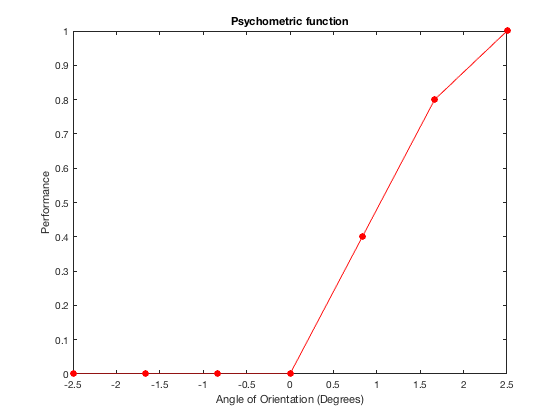


% We will be displaying our Gabors either above or below fixation by 250
% pixels. We therefore have to determine these two locations in screen
% coordianates.
pixShift = 250;
xPos = [xCenter xCenter];
yPos = [yCenter - pixShift yCenter + pixShift];

% Count how many Gabors there are (two for this demo)
nGabors = numel(xPos);

% Make the destination rectangles for  the Gabors in the array i.e.
% rectangles the size of our Gabors cenetred above an below fixation.
baseRect = [0 0 gaborDimPix gaborDimPix];
allRects = nan(4, nGabors);
for i = 1:nGabors
    allRects(:, i) = CenterRectOnPointd(baseRect, xPos(i), yPos(i));
end

% Randomise the phase of the Gabors and make a properties matrix.
phaseLine = rand(1, nGabors) .* 360;
propertiesMat = repmat([NaN, freq, sigma, contrast,...
    aspectRatio, 0, 0, 0], nGabors, 1);
propertiesMat(:, 1) = phaseLine';

% Set the orientations for the methods of constant stimuli. We will center
% the range around zero (vertical) and give it a range of 1.8 degress, this
% will mean we test between -(1.8 / 2) and +(1.8 / 2). Finally we will test
% seven points linearly spaced between these extremes.
baseOrientation = 0;
orRange = 5;
numSteps = 7;
stimValues = linspace(-orRange / 2, orRange / 2, numSteps) + baseOrientation;

% Now we set the number of times we want to do each condition, then make a
% full condition vector and then shuffle it. This will randomly order the
% orientation we present our Gabor with on each trial.
numRepeats = 5;
condVector = Shuffle(repmat(stimValues, 1, numRepeats));

% Calculate the number of trials
numTrials = numel(condVector);

% Make a vector to record the response for each trial
respVector = zeros(1, numSteps);

% Make a vector to count how many times we present each stimulus. This is a
% good check to make sure we have done things right and helps us when we
% input the data to plot anf fit our psychometric function
countVector = zeros(1, numSteps);


%----------------------------------------------------------------------
%                       Timing Information
%----------------------------------------------------------------------

% Presentation Time for the Gabor in seconds and frames
presTimeSecs = 0.2;
presTimeFrames = round(presTimeSecs / ifi);

% Interstimulus interval time in seconds and frames
isiTimeSecs = 1;
isiTimeFrames = round(isiTimeSecs / ifi);

% Numer of frames to wait before re-drawing
waitframes = 1;


%----------------------------------------------------------------------
%                       Keyboard information
%----------------------------------------------------------------------

% Define the keyboard keys that are listened for. We will be using the left
% and right arrow keys as response keys for the task and the escape key as
% a exit/reset key
escapeKey = KbName('ESCAPE');
leftKey = KbName('LeftArrow');
rightKey = KbName('RightArrow');


%----------------------------------------------------------------------
%                       Experimental loop
%----------------------------------------------------------------------

% Animation loop: we loop for the total number of trials
for trial = 1:numTrials

    % Get the Gabor angle for this trial (negative values are to the right
    % and positive to the left)
    theAngle = condVector(trial);

    % Randomise the side which the Gabor is displayed on
    side = round(rand) + 1;
    thisDstRect = allRects(:, side);

    % Change the blend function to draw an antialiased fixation point
    % in the centre of the screen
    Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

    % If this is the first trial we present a start screen and wait for a
    % key-press
    if trial == 1
        DrawFormattedText(window, 'Press Any Key To Begin', 'center', 'center', black);
        Screen('Flip', window);
        KbStrokeWait;
    end

    % Flip again to sync us to the vertical retrace at the same time as
    % drawing our fixation point
    Screen('DrawDots', window, [xCenter; yCenter], 10, black, [], 2);
    vbl = Screen('Flip', window);

    % Now we present the isi interval with fixation point minus one frame
    % because we presented the fixation point once already when getting a
    % time stamp. We dont really need a loop here, we could use a value of
    % waitframnes greater than one. However, as we are using a loop below,
    % I have also used a loop here.
    for frame = 1:isiTimeFrames - 1

        % Draw the fixation point
        Screen('DrawDots', window, [xCenter; yCenter], 10, black, [], 2);

        % Flip to the screen
        vbl = Screen('Flip', window, vbl + (waitframes - 0.5) * ifi);
    end

    % Now we draw the Gabor and the fixation point
    for frame = 1:presTimeFrames

        % Set the right blend function for drawing the gabors
        Screen('BlendFunction', window, 'GL_ONE', 'GL_ZERO');

        % Draw the Gabor
        Screen('DrawTextures', window, gabortex, [], thisDstRect, theAngle, [], [], [], [],...
            kPsychDontDoRotation, propertiesMat');

        % Change the blend function to draw an antialiased fixation point
        % in the centre of the array
        Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

        % Draw the fixation point
        Screen('DrawDots', window, [xCenter; yCenter], 10, black, [], 2);

        % Flip to the screen
        vbl = Screen('Flip', window, vbl + (waitframes - 0.5) * ifi);
    end


    % Change the blend function to draw an antialiased fixation point
    Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

    % Draw the fixation point
    Screen('DrawDots', window, [xCenter; yCenter], 10, black, [], 2);

    % Flip to the screen
    vbl = Screen('Flip', window, vbl + (waitframes - 0.5) * ifi);

    % Now we wait for a keyboard button signaling the observers response.
    % The left arrow key signals a "left" response and the right arrow key
    % a "right" response. You can also press escape if you want to exit the
    % program
    respToBeMade = true;
    while respToBeMade
        [keyIsDown,secs, keyCode] = KbCheck;
        if keyCode(escapeKey)
            ShowCursor;
            sca;
            return
        elseif keyCode(leftKey)
            response = 1;
            respToBeMade = false;
        elseif keyCode(rightKey)
            response = 0;
            respToBeMade = false;
        end
    end

    % Record the response
    respVector(stimValues == theAngle) = respVector(stimValues == theAngle)...
        + response;

    % Add one to the counter for that stimulus
    countVector(stimValues == theAngle) = countVector(stimValues == theAngle) + 1;

end

data = [stimValues; respVector; countVector]';

figure;
plot(data(:, 1), data(:, 2) ./ data(:, 3), 'ro-', 'MarkerFaceColor', 'r');
axis([min(data(:, 1)) max(data(:, 1)) 0 1]);
xlabel('Angle of Orientation (Degrees)');
ylabel('Performance');
title('Psychometric function');


% Clean up
sca;



INFO: PTB's Screen('Flip', 10) command seems to have missed the requested stimulus presentation deadline
INFO: a total of 2 times out of a total of 2562 flips during this session.

INFO: This number is fairly accurate (and indicative of real timing problems in your own code or your system)
INFO: if you provided requested stimulus onset times with the 'when' argument of Screen('Flip', window [, when]);
INFO: If you called Screen('Flip', window); without the 'when' argument, this count is more of a ''mild'' indicator
INFO: of timing behaviour than a hard reliable measurement. Large numbers may indicate problems and should at least
INFO: deserve your closer attention. Cfe. 'help SyncTrouble', the FAQ section at www.psychtoolbox.org and the
INFO: examples in the PDF presentation in PsychDocumentation/Psychtoolbox3-Slides.pdf for more info and timing tips.

